# Project 3

Ross Smyth

clc, clear, close all
run p3ModelRun
clearvars -except BCB SF rod brick gravity

This report goes over the development, implementation, and verification of models for Project 3 in the class MEEM 4730. This project is a model of a block and rod system. This system is modeled both "directly" with differential equations derived from Lagrange's equation, and "indirectly" with Simulink's Simscape enviroment. Assumtions in this model include: all joints are frictionless, air resistance is negligible, no mass is consumed by the thrusters, the thrusters are firing from the center of mass of the rods, and that all objects are rigid bodies. For this project the full non-linear dynamics are explored, and two input profiles are implmented. A bang-coat-bang controller, and a swing-free profile .The bang-cost-bang is essentially two pulse with a dead time in between. The swing-free manuver attmepts to use the natural dynamics of the rods to reduce the swinging of the rods and the drift of the brick after the manuver is complete.

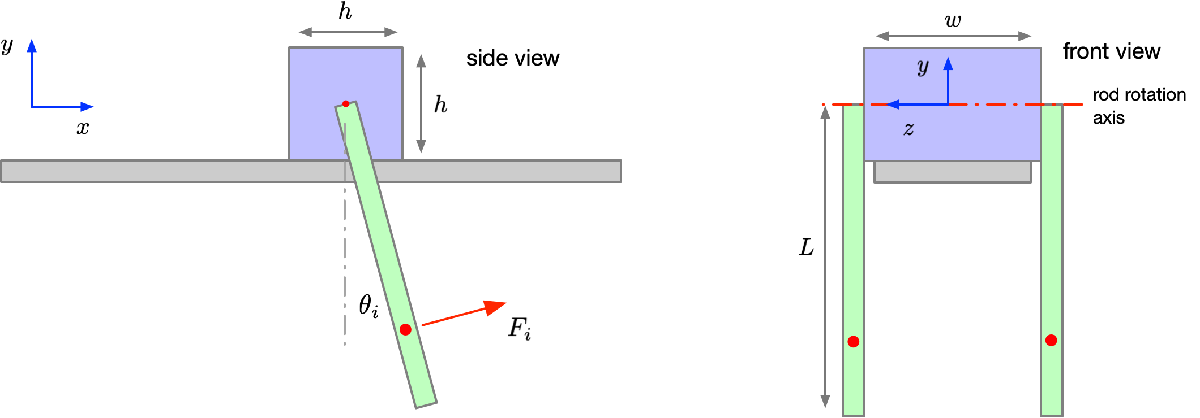

*Model diagram*

## Differential Equation Model

### Intro

This sytem is a non-linear system, and to simulate the dynamics a differential equation model was developed that defines the equations of motion. A each time step the current state of the system is input to this model, from which the derivatives of each of the parameters can be found, which is then integrated to get the next set of states. The full differential equation derivation is shown step-by-step in Appendix A.

This system is defined with a set of coupled, ordinary differential equations. These equations were derived via a reformulation of classical, Newtonian, mechanics called analytical mechanics, specifically Lagrangian mechanics in this case. This reformulation allows one to derive the equations of motion for a complicated system as long as some generlized coordintes of the system can be defined, and the kinetic and potential energy can be defined in terms of these coordinates. Once the energies are defined, the potential energy is subtracted from the kinetic energy to form a scalar expression of this energy difference called the Lagrangian. The Lagrangian can be put through Lagrange's equation for each generlized coordnate, and the equation of motion for that coordniate will be output. Below is Lagrange's equation, where L represents the Lagrangian, and Q represents generlized power, which expresses external forces on the system.


$$\frac{\partial }{\partial t }\left(\frac{\partial }{\partial {\dot{q_i } } }L\right)-\frac{\partial }{\partial {q_i } }L=Q_i$$


For the system at-hand, the generlized coordinates used are the following:


$$\begin{array}{l}
x_b =\textrm{Brick}\;\textrm{position}\\
\theta_1 =\textrm{Rod}\;1\;\textrm{angle}\\
\theta_2 =\textrm{Rod}\;2\;\textrm{angle}
\end{array}$$


### Kinematics and energy

The next step towards obtaining the equations of motion is defining the kinematics and the energies. For kinematics, this essentially means representing any relationships between items in the system. Even though the position is not one of the generalized coordinates, it is still needed to calculate the linear kinetic energy of the rods. For this system it is clear that the absolute position of the rods is dependent on the position of the block, so that relationship is shown below. The brick's position vector is also shown for clarity.


$$\begin{array}{l}
\overrightarrow{x_b } =\left\lbrack \begin{array}{c}
x_b \\
0\\
0
\end{array}\right\rbrack \\
{{\overrightarrow{x} }_{\textrm{rod}} }_j =\overrightarrow{x_b } +\frac{L}{2}\left\lbrack \begin{array}{c}
\sin \left(\theta_j \right)\\
-\cos \left(\theta_j \right)\\
\pm \frac{w}{2}
\end{array}\right\rbrack 
\end{array}$$


Where L is the length of the rods, and w is the width of the brick. From this set (one for each rod) of definitions the kinematics are done. Next the energy of the system is calculated. For the rods, the energy definition is the same for each of them with both linear kinetic energy, rotational kinetic energy, and graviational potential energy. For the brick, if the zero of the gravitational potential is placed at its center of mass there is only liner kinetic energy. Below shows the kinetic energy expression, T, for the rods and brick.


$$\begin{array}{l}
T_{{\textrm{rods}}_j } =\frac{1}{2}\left\lbrack M_r \;\left\langle {{\dot{\overrightarrow{x} } }_{\textrm{rod}} }_j \;,\;{{\dot{\overrightarrow{x} } }_{\textrm{rod}} }_j \right\rangle +\frac{M_r \left(3r^2 +L^2 \right)}{12}{{\theta^˙ }_j }^2 \right\rbrack \\
T_{\textrm{brick}} =\frac{1}{2}\left\lbrack M_b \;\left\langle \dot{\overrightarrow{x_b } \;} ,\;\dot{\overrightarrow{x_b } } \right\rangle \right\rbrack 
\end{array}$$


And the potential energies:


$$V_{{\textrm{rod}}_j } =-M_r g\frac{L}{2}\cos \left(\theta_j \right)$$


Where $M_r \;$represents the mass of the rods, $M_b$ represents the mass of the brick,  $r$ represents the radius of the rods, and $\left\langle \overrightarrow{a} ,\overrightarrow{b} \right\rangle$ represents the vector dot product. From these the Lagranian expression can be calculated by the sum of all three kinetic energies subtracted by the sum of both of the potential energies.


$$L=\sum T_i -\sum V_i$$


### Generalized Forces

For a given system, if there are any non-constraint external forces they must be represented in terms of generalized power. This generalized power is the dot product of the generlized force and the time derivative of generlized coordinates effected. For this case the generalized power is represented with an actual mechanical power equation, as it is a linear force applied to the rods, and the absolute position was calculated above.


$$\begin{array}{l}
F_j =\left\lbrack \begin{array}{c}
\cos \left(\theta_j \right)\\
\sin \left(\theta_j \right)\\
0
\end{array}\right\rbrack \\
Q=\left\langle F_1 \;,\;{{\dot{\overrightarrow{x} } }_{\textrm{rod}} }_1 \right\rangle +\left\langle F_2 \;,\;{{\dot{\overrightarrow{x} } }_{\textrm{rod}} }_2 \right\rangle 
\end{array}$$


This results in the generalized power expression, which can then be converted to a matrix equation in terms of the time derivative of the generalized coordnate as the equations are linear in terms of them.


$$Q=\left\lbrack \begin{array}{ccc}
F_1 \cos \left(\theta_1 \right)+F_2 \cos \left(\theta_2 \right) & \frac{F_1 L}{2} & \frac{F_2 L}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{x_b } \\
{\theta^˙ }_1 \\
{\theta^˙ }_2 
\end{array}\right\rbrack$$


These equations make sense, as the force on the block only matter in the x direction, and the generalized force upon the rods are torques half-way along their lengths.

### Equations of Motion

With these defined, and the previous energy definitions, the equation of motion can be calculated. For each of the generalized coordinates, $x_b ,\theta_1 ,\textrm{and}\;\theta_2$ Lagrange's equation can be applied to the Lagrangian. This results in a set of time-varying equations that are linear in terms of the second time derivative of the generalized coordinates. Because of this, a matrix equation in the form of $Ax=B$ can be formed. In this case the A would be a 3x3 mass matrix, representing the intertia terms, x would be the second time derivatives of the generalized coordinates, and B would be the right-hand side of coupled equations that define the motion. These are shown below.


$$\left\lbrack \begin{array}{ccc}
M_b +2M_r  & \frac{L\;M_r }{2}\;\cos \left(\theta_1 \right) & \frac{L\;M_r }{2}\;\cos \left(\theta_2 \right)\\
\frac{L\;M_r }{2}\;\cos \left(\theta_1 \right) & \frac{M_r }{12}\;\left(4\;L^2 +3\;r^2 \right) & 0\\
\frac{L\;M_r }{2}\;\cos \left(\theta_2 \right) & 0 & \frac{M_r }{12}\;\left(4\;L^2 +3\;r^2 \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\ddot{x} }_b \\
{\theta^¨ }_1 \\
{\theta^¨ }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{L\;M_r \;{\theta^˙ }_1^2 }{2}\;\sin \left(\theta_1 \right)+\frac{L\;M_r \;{\theta^˙ }_2^2 }{2}\;\sin \left(\theta_2 \right)+F_1 \;\cos \left(\theta_1 \right)+F_2 \;\cos \left(\theta_2 \right)\\
\frac{L}{2}\left(F_1 -M_r \;g\;\sin \left(\theta_1 \right)\right)\\
\frac{L}{2}\left(F_2 -M_r \;g\;\sin \left(\theta_2 \right)\right)
\end{array}\right\rbrack$$


With this equation, the dynamics of the system can be simulated with the following process:

- Input system states into the mass matrix and right-hand side vector to get a system of linear equations.

- Solve the system of linear equations $\ddot{\overrightarrow{q} } =M^{-1} R$, then concentate with the previous time-step's generalized velocities.

- Integrate the generlized accelerations and velocities to get the new time step's generalized coordinates and their time derivatives.

- Go to step 1

## Implementation and Outputs

This ssytem was implemented with two models. Directly with the above differential equation, and also indirectly with Simscape,  Simulink's acasual simulation enviroment. Rather than directly building a differential equation model, this enviroment allows for an engineer to put together discrete components such as masses and joints, which allows for greater physical intuition on the system. Both of these models shared the same inputs, either a bang-coast-bang controller, or a swing-free manuver.

#### Simulink

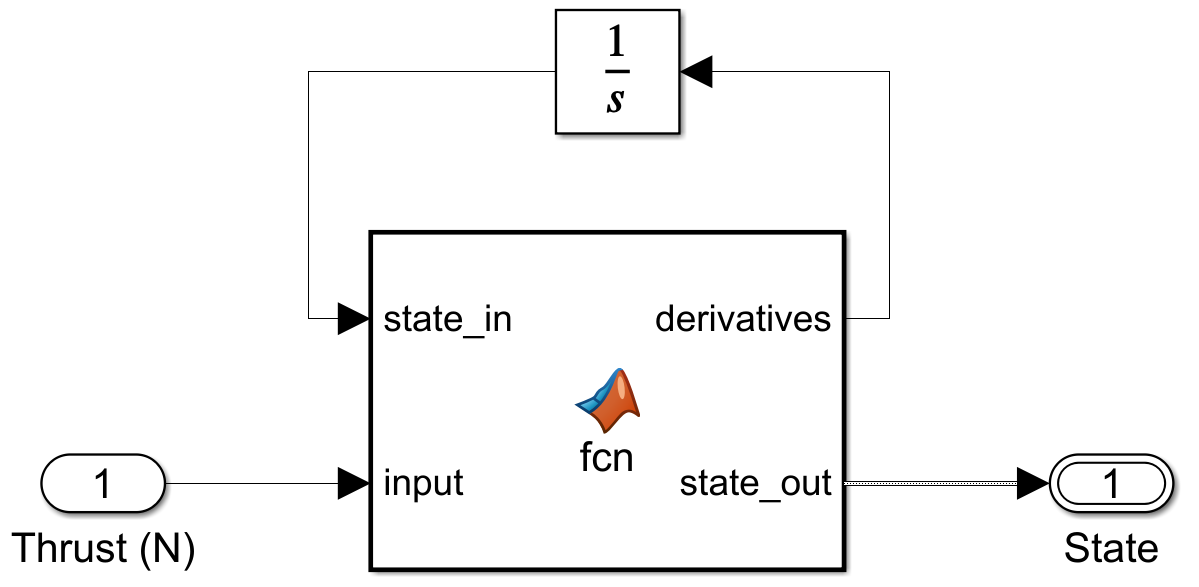

*Simulink Differential Equation Model Solver*

#### Simscape

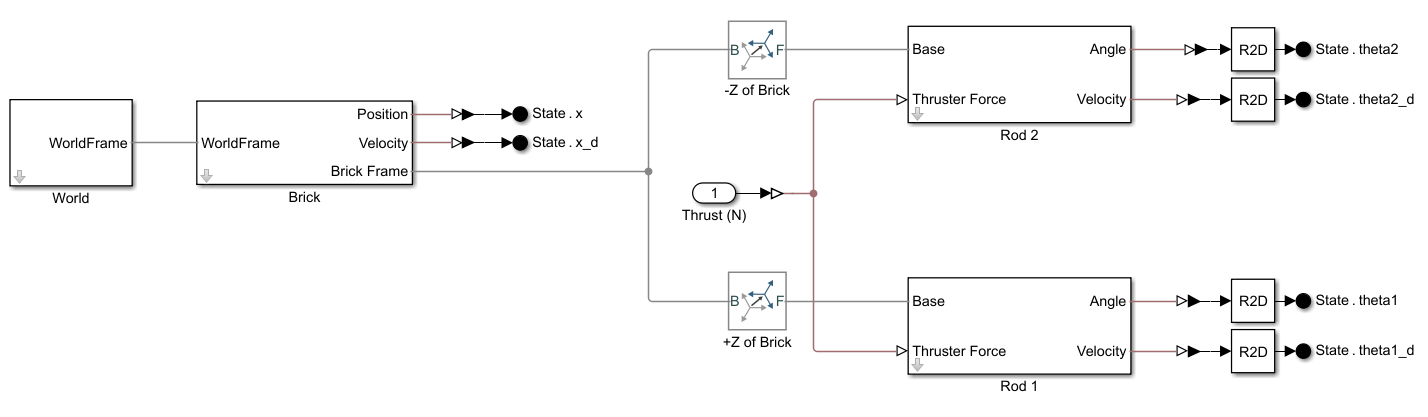

*Overall Simscape Model*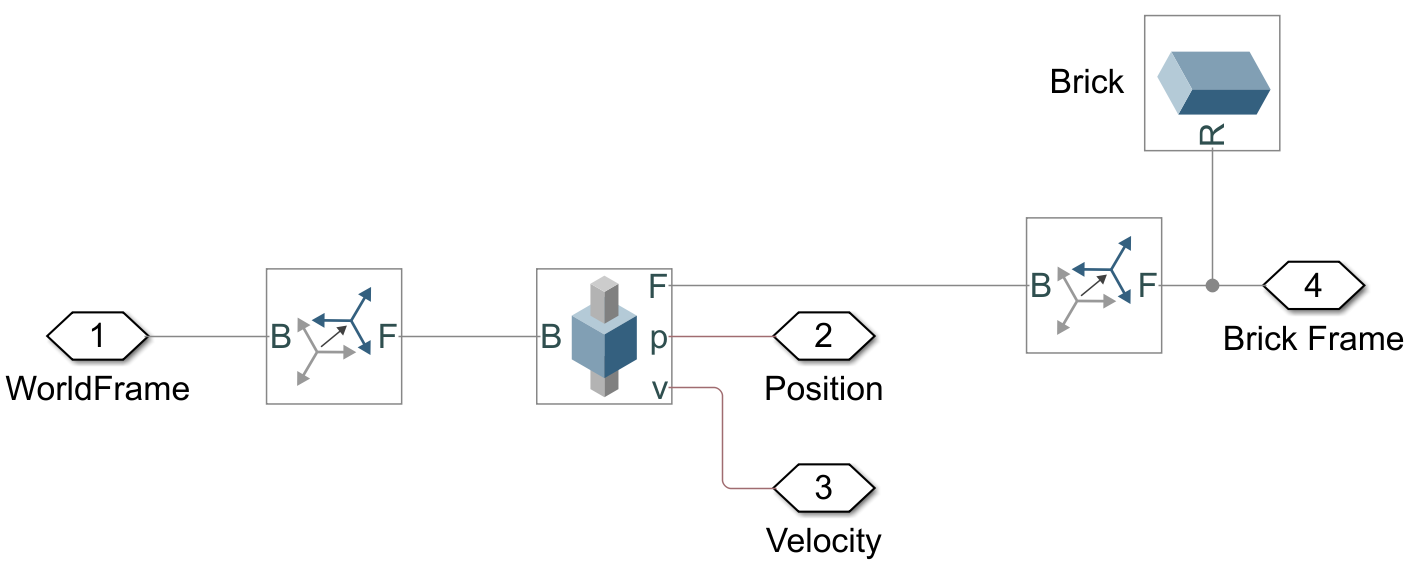

*Brick Subsystem*

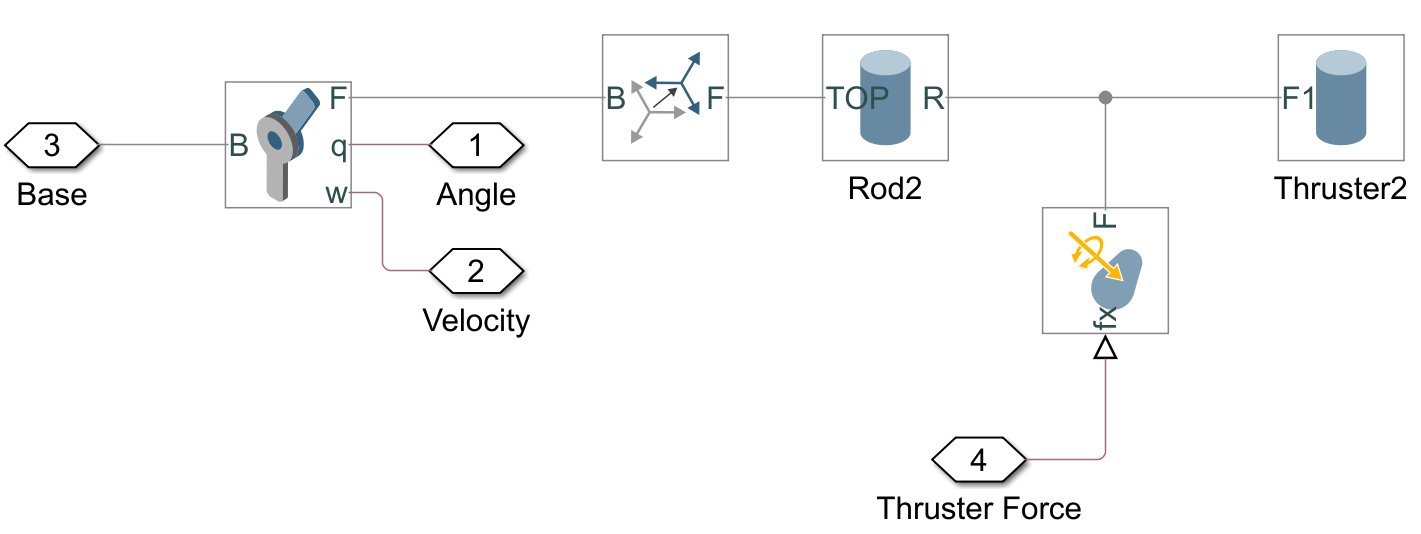

*Rod Subsystem*

#### Outputs

Below shows the output of the differential equation model (as the Simscape is nearly identical, see the verification section below), for both the bang-coast-bang controller and the swing-free manuever.

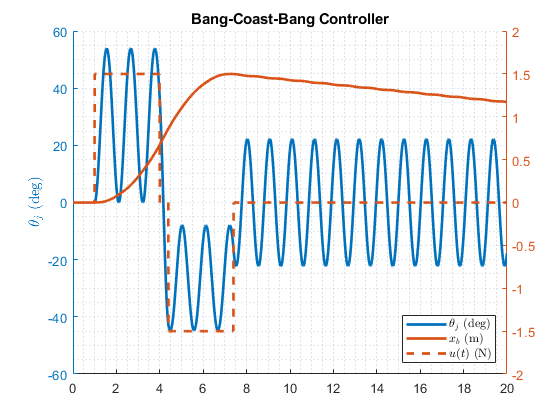

figure()

yyaxis left
hold on
ph = plot(BCB.DiffEq.theta1);
ylabel("$\theta_j$ (deg)", 'Interpreter',"latex")
set(ph, "LineWidth", 2)
hold off

yyaxis right
hold on
ph = plot(BCB.DiffEq.x);
set(ph, "LineWidth", 2)
ph = plot(BCB.Thrust);
set(ph, "LineWidth", 2)
ylim([-2, 2])
hold off

legend('$\theta_j$ (deg)', '$x_b$ (m)', '$u(t)$ (N)', 'Interpreter', 'latex', 'location', 'southeast')
title("Bang-Coast-Bang Controller")
grid minor

This shows that after end of the manuever, the system drifts away from the end location. This makes sense as the thruster input may not have cancelled out all of the linear momentum of the system if the rod angles' were not at exactly zero degees.

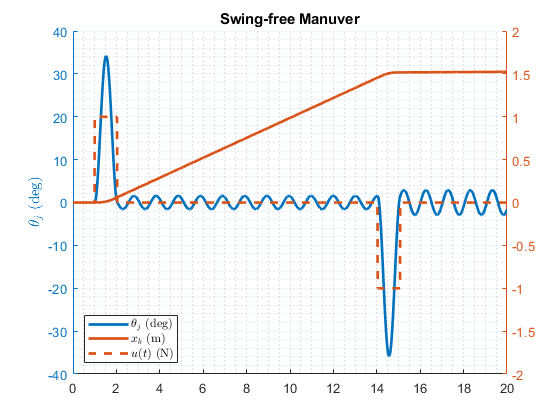

figure()

yyaxis left
hold on
ph = plot(SF.DiffEq.theta1);
ylabel("$\theta_j$ (deg)", 'Interpreter',"latex")
set(ph, "LineWidth", 2)
hold off

yyaxis right
hold on
ph = plot(SF.DiffEq.x);
set(ph, "LineWidth", 2)
ph = plot(SF.Thrust);
set(ph, "LineWidth", 2)
ylim([-2, 2])
hold off

legend({'$\theta_j$ (deg)', '$x_b$ (m)', '$u(t)$ (N)'}, 'Interpreter', 'latex', 'location', 'southwest')
title("Swing-free Manuver")
grid minor

With the swing-free manuver it seems that because the force input time was approximatly the same as the period of the rods' swinging behavior, the momentum of the system was cancelled out extremly well. There is  minimal drift from the endpoint.

## Verification

With the models implemented, verification is the next step. Because there are two models, and there isn't an analytical solution to this system verification must be done between models, and verifying that conservation laws are followed. Below show the error between the two models.

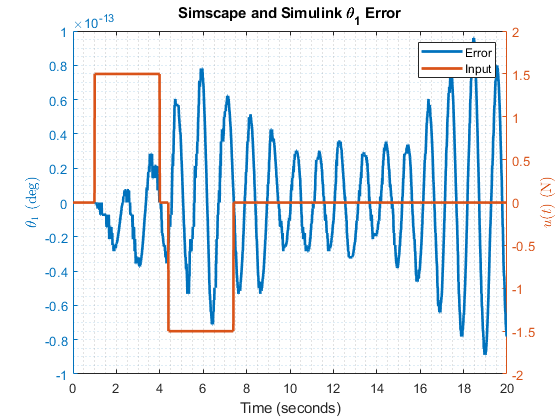

figure()

yyaxis left
ph = plot(BCB.Simscape.theta1 - BCB.DiffEq.theta1);
ylabel("$\theta_1$ (deg)", 'Interpreter',"latex")
set(ph, "LineWidth", 2)

yyaxis right
ph = plot(BCB.Thrust);
ylabel("$u(t)$ (N)", 'Interpreter',"latex")
set(ph, "LineWidth", 2)
ylim([-2, 2])

legend('Error', 'Input')
title("Simscape and Simulink \theta_1 Error")
grid minor

The above plot shows that the error between the two models is on the order of ${10}^{-13}$degrees, which is extremly small (the most accurate spacecraft pointing system in the world, the Hubble Space Telescope's, is only accurate to ${10}^{-6}$ degrees) and so it is safe to say that the models are essentially identical. The error increases when the dynamics are faster, and also as time goes on it can be seen that the error increases. If ran for a long time a different integration scheme or a smaller timestep may need to be used.

Another way for verification is checking the conservation laws of the system. In this case energy will be checked, but momentum should be checked as well to ensure full conservation. Only the differential equation models' energy will be shown as above it is shown that the models are nearly identical, so if it conserves energy well, then the Simscape model will as well. Specifically the power will be looked at in detail, during periods were there is no input, the change in energy with time should be zero. The bang-coast-bang controller will be analyzed as the dynamics of that manuever are faster than the dynamics of the swing-free manuver.

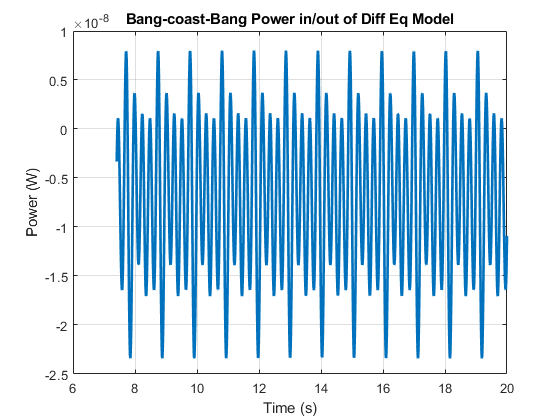

kinetic   = KineticEnergy(1, rod.l, brick.m, rod.m, rod.r, deg2rad( BCB.DiffEq.theta1_d.Data ), deg2rad( BCB.DiffEq.theta2_d.Data ), deg2rad( BCB.DiffEq.theta1.Data ), deg2rad( BCB.DiffEq.theta2.Data ), BCB.DiffEq.x_d.Data);
potential = -rod.l * rod.m * gravity/2 * (cosd(BCB.DiffEq.theta1.Data) + cosd(BCB.DiffEq.theta2.Data));
energy = kinetic+potential;
power  = diff(energy);

figure()
ph = plot(BCB.DiffEq.theta1_d.Time(742:end), power(741:end)/diff(BCB.DiffEq.theta1_d.Time(1:2)));
ylabel('Power (W)')
xlabel('Time (s)')
title('Bang-coast-Bang Power in/out of Diff Eq Model')

grid on
set(ph, "LineWidth", 2)

The above plot shows the power in/out of the system of the differential equation model after the bang-coast-bang manuever is performed. Theoretically the power should be zero, but since this is a numerical model this will not be the case. The energy in out of the system at each time step is minimal, and it looks to keep stay near zero, and not diverge. This verifies that energy is conserved well over short time-scales, though if simluated for extremly long periods (decades) or if the dynamics of the system remain high for long periods, the leakage of energy may be a concern.

## Conclusion

In conclusion, this system model is at least verified between two independent models, one derived using Lagrange's equation, and another put together using Simscape. It is also verfied to conserve energy relatively well. For next steps, building the system in real life and validating the model against real data would be a good next step, or making less assumptions about the system. The assumptions mentioned in the introduction can be reduced with some of the following techniques. 

For implementing friction and/or air resistance, Rayleigh's dissipation function would be needed to be used for the velocity dependence. Columb friction would have to use a modified version of this as it does not have a linear dependece with velocity like viscous friction does. For air resistance if the linear resistance model is used then Rayleigh's dissipation function can be used, but if the quadratic model is used it would need to be modified.

Implementing varying mass for the thrusters would not be extremly hard, the main difference would that [the mass in the energy expression would have a time dependence](https://arc.aiaa.org/doi/abs/10.2514/3.1626). Out of all the assumption, if the rigid body assumption did not hold, which would occur if the fundemental frequency of the rod was low relative to the dynamics of the system, it would be the most difficult to correct. This would require implementing a (hopefully) simplified partial differential equation model of the rods.

With this model, an engineer can experiment with different thrust profiles and observe how the system changes. For the bang-coast-bang profile an engineer can observe how certain thrust profiles behave in steady-state after the manuver is done, or how the transient dynamics are, for example the maximum angle of the rod. With the swing-free profile, with small thrusts the rods can be stablised at the end of the manuver easily, allowing for stable movements of the brick and rod. Engineers can explore the maximum thrusts that can be used, as once the rods reach a high enough angle the natrual frequency can no longer be assumed to be constant. Since this fully simulates the non-linear dynamics the full range can be explored. Then engineers can implement the profile on a real system and be assured that the model is closer than a linaer model would.

## Appendix A